# USV Proportional Control Design

## USV Surge Proportional Control

**Sketch the unity feedback block diagram. **

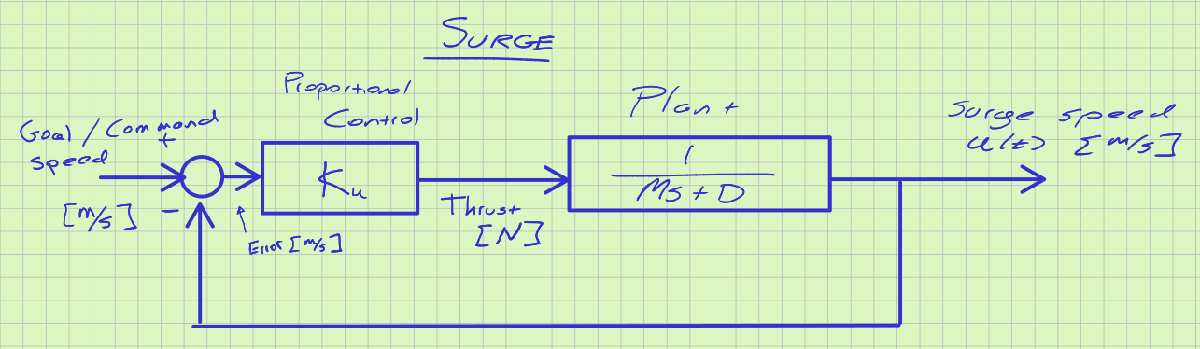

**Calculate the closed-loop transfer function**


$$T_u(s) = \frac{K_u}{Ms + (D+K_u)} = \left(\frac{K_u}{D+K_u}\right) \cdot \frac{ 1 } { \left(\frac{M}{D+K_u}\right) s + 1}.
$$


We can identify that the close-loop system is first-order, the time constant is


$$\tau = M/(D+K_u)$$


and the DC gain of the system is


$$K_{dc} =  K_u/(D+K_u)
$$


which tells us that the overshoot will always be zero and that as we increase $K_u$, the time constant will increase and the gain will approach 1.0. 

**Find %OS and Settling Time for **$K_u = 1.0$

Because $T_u$ is first-order, %OS is always zero.

Settling time: $T_s = \frac{4}{a} = 4 \, \tau = 4 \, \left(\frac{M}{D+K_u}\right) = 4\, \left(\frac{36}{18.75 + 1}\right) = 7.3 \, s$

**Generate the plant transfer function**

% Parameters
M = 36;
D = 18.75;
% Plant
Gu = tf(1,[M D])


Gu =
 
       1
  ------------
  36 s + 18.75
 
Continuous-time transfer function.
Model Properties


**Closed-loop transfer function**

Ku = 1.0;  
Gcl = feedback(Ku*Gu, 1)


Gcl =
 
       1
  ------------
  36 s + 19.75
 
Continuous-time transfer function.
Model Properties


**Evaluate step response**

figure;
clf;
step(Gcl)
stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 4.0047
    TransientTime: 7.1309
     SettlingTime: 7.1309
      SettlingMin: 0.0458
      SettlingMax: 0.0506
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0506
         PeakTime: 13.3468


ylabel('Surge (m/s)')

I put the metrics in the figure title, but this is not necessary.  You can simply report the final values with the exercise, so you can safely ignore the following code block.

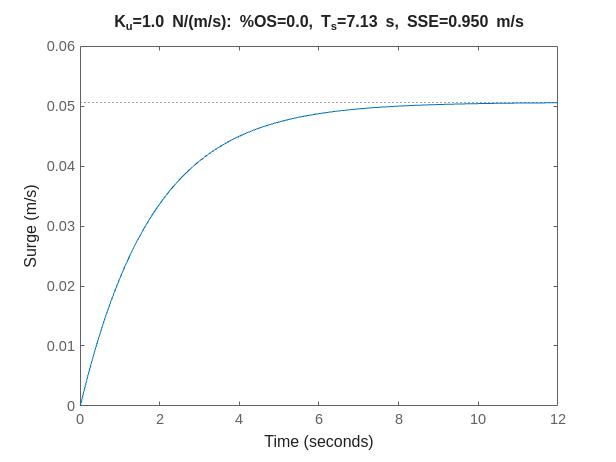

% Steady state error
[yy,tt]=step(Gcl);
sse = abs(1-yy(end));
s = stepinfo(Gcl);
title(sprintf("K_u=%.1f N/(m/s): %%OS=%.1f, T_s=%0.2f s, SSE=%.3f m/s",...
    Ku, s.Overshoot, s.SettlingTime, sse));

**Tuning**

Iteratively change $K_u$ to deduce the effect of the control gain on the closed-loop step response.

- Notice that the closed-loop response is first-order, so there will never be any overshoot.

- The higher you turn up $K_u$, the smaller the closed-loop time constant, the faster the system and the less the settling time.

- The higher you turn up $K_u$, the smaller the steady state error.  It never goes to zero, but is always a constant.

The tuning is iterative, so you change this number...

% Change gain
Ku = 77;  

And re-evaluate the response until it meets the design constraints.

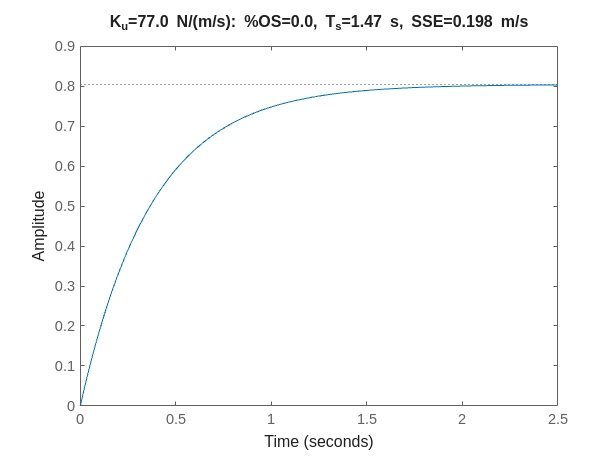

% Close the loop
Gcl = feedback(Ku*Gu, 1);
% Evaluate the response.
figure;
clf;
step(Gcl)
[yy,tt]=step(Gcl);
sse = abs(1-yy(end));
s = stepinfo(Gcl);
title(sprintf("K_u=%.1f N/(m/s): %%OS=%.1f, T_s=%0.2f s, SSE=%.3f m/s",...
    Ku, s.Overshoot, s.SettlingTime, sse));

Any value of $K_u$ above roughly 77 should satisfy the design.

## Yaw Proportional Control

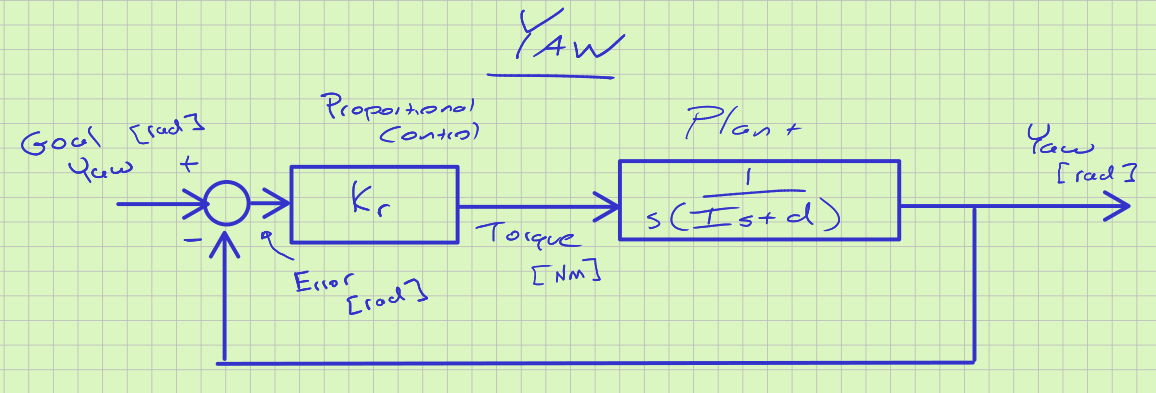

For yaw control, the plant transfer function is different and the resulting closed-loop equivalent transfer function is

$T_r(s) = \frac{K_r}{Is^s + ds +K_r} = \frac{K_r/I}{s^s + (d/I) s + (K_r/I)}
$.

Comparing this to our canonical second-order transfer funtion, we note the following:

- The DC gain is always 1.0, independent of the proportioanl control gain - so at steady-state the input and output will be the same, so zero steady state error.  

- The natural frequency, $\omega_n = \sqrt{K_r/I$will increase with increasing $K_r$ and 

- The damping ratio $\zeta = (D/I) / (2 \omega_n)$ will decrease with increasing $K_r$  - which means turning up the control gain will generate increasing overshoot  

**Find %OS and Settling Time for **$K_r = 1.0$

Kr = 1.0;
I = 8.35;
d = 24;
omega_n = sqrt(Kr/I)

omega_n = 0.3461

zeta = (d/I)/(2*omega_n)

zeta = 4.1528

Since $\zeta > 1$, the system is overdamped, so %OS will be zero.

Since the system has two, distinct, real poles, this is two first order systems in series.  We can estimate the settling time as the settling time of the slowest first order system.  We can find the poles like this...

roots([1 2*zeta*omega_n omega_n^2])

ans =    -2.8320
   -0.0423


Since the time constant is the reciprocol of the pole locatoin, the slowest pole is the root at 


$$a = -0.0433 \rightarrow \tau=1/a = 24 \, \text{s}$$



$$T_s \approx 4 \, \tau = 96 \, \text{s}$$


**Generate the plant transfer function**

% Plant
Gr = tf(1,[I d 0])


Gr =
 
         1
  ---------------
  8.35 s^2 + 24 s
 
Continuous-time transfer function.
Model Properties


**Closed-loop transfer function**

Kr = 1.0;  
Gcl = feedback(Kr*Gr, 1)


Gcl =
 
           1
  -------------------
  8.35 s^2 + 24 s + 1
 
Continuous-time transfer function.
Model Properties


**Evaluate step response**

figure;
clf;
step(Gcl)
stepinfo(Gcl)

ans = struct with fields:
         RiseTime: 51.9575
    TransientTime: 92.8680
     SettlingTime: 92.8680
      SettlingMin: 0.9031
      SettlingMax: 0.9993
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9993
         PeakTime: 173.1477


ylabel('Yaw (rad)')

I put the metrics in the figure title, but this is not necessary.  You can simply report the final values with the exercise, so you can safely ignore the following code block.

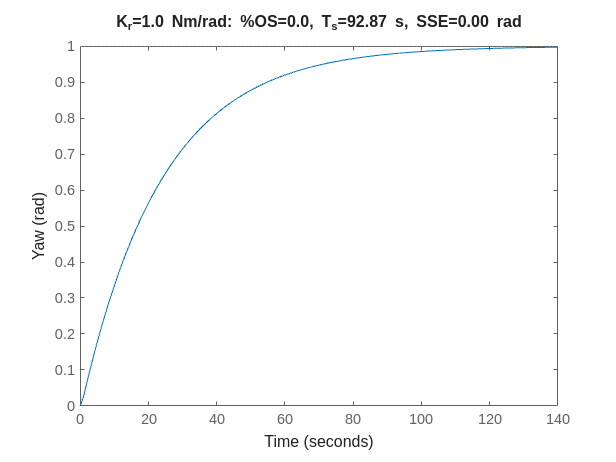

% Steady state error
[yy,tt]=step(Gcl);
sse = abs(1-yy(end));
s = stepinfo(Gcl);
title(sprintf("K_r=%.1f Nm/rad: %%OS=%.1f, T_s=%0.2f s, SSE=%.2f rad",...
    Kr, s.Overshoot, s.SettlingTime, sse));

**Tuning**

Iteratively change $K_r$ to deduce the effect of the control gain on the closed-loop step response.

- The steady-state error is always zero - the system always asymptotically approaches 1.0.

- As we increase $K_r$,  the speed of the system increases, it is more reponsive.  $T_s$ decreases initially, but if the gain is too high, the settling time begins to increase again.

- As we increase $K_r$, the damping ratio decreases and the overshoot increases.

We need to find a value for $K_r$ that balances the speed of the response while not having too much overshoot. 

The tuning is iterative, so you change this number...

% Change gain
Kr = 50;  

And re-evaluate the response until it meets the design constraints.

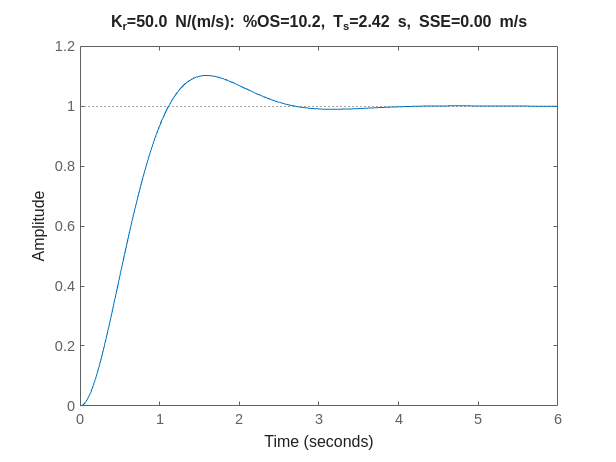

% Close the loop
Gcl = feedback(Kr*Gr, 1);
% Evaluate the response.
figure;
clf;
step(Gcl)
[yy,tt]=step(Gcl);
sse = abs(1-yy(end));
s = stepinfo(Gcl);
title(sprintf("K_r=%.1f N/(m/s): %%OS=%.1f, T_s=%0.2f s, SSE=%.2f m/s",...
    Kr, s.Overshoot, s.SettlingTime, sse));

There is a range of values that meet the design constraints.  The range is approximatley between 50-60.  You only need to find one value that satisfies the constaints.

**Estimating the range of acceptable values.**

This section can be safely ignored.  To find the range of acceptable values we might do something like this...

kk = 40:5:70;
os = [];
ts = [];

for ii = 1:length(kk)
    k = kk(ii);
    Gcl = feedback(k*Gr, 1);
    s = stepinfo(Gcl);
    os(end+1)=s.Overshoot;
    ts(end+1)=s.SettlingTime;
end
T = table(kk', os', ts', 'VariableNames', ...
    ["Gain", "%OS", "T_s"])

T = 7×3 table
    Gain     %OS       T_s  
    ____    ______    ______

     40     6.4871    2.7461
     45     8.4033     2.574
     50     10.225    2.4185
     55     11.964    2.2816
     60     13.593    2.1619
     65     15.139    2.8278
     70     16.593    2.8006
